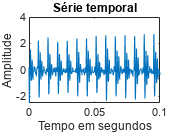

% Carrega os dados para análise
data = load('Voz.mat');

% Carrega os valores de tempo
t = data.t;
t = t(:); % Transforma em vetor coluna

% Carrega os valores da amplitude
Vp = data.Vp;
Vp = Vp(:); % Transforma em vetor coluna

% Exibe a serie temporal carregada
figure;
plot(t, Vp);
title('Série temporal');
xlabel('Tempo em segundos');
ylabel('Amplitude');

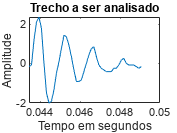


% Separa um trecho do sinal (Escolhido manualmente)
tempoInicial = 348; % posição no vetor t
tempoFinal = 393;

% Recorta os trechos
trecho_t = t(tempoInicial:tempoFinal);
trecho_Vp = Vp(tempoInicial:tempoFinal);

% Exibe o trecho recortado
figure;
plot(trecho_t, trecho_Vp);
title('Trecho a ser analisado');
xlabel('Tempo em segundos');
ylabel('Amplitude');


% Encontrar picos
[peaks,peak_indices ]= findpeaks(trecho_Vp);
t_peaks = trecho_t(peak_indices);


% Frequência
peaks_distance = diff(t_peaks);
% for i=1:1:length(peaks)
%     peaks_distance = horzcat(trecho_t(peaks(i + 1))- trecho_t(peaks(i)));
% end
mean_distance = mean(peaks_distance);
trecho_freq = 1 / mean_distance;
trecho_omega = trecho_freq * 2 * pi;

fprintf('Frequência aproximada do trecho: %f Hz e ω = %f\n', trecho_freq, trecho_omega);

Frequência aproximada do trecho: 705.000000 Hz e ω = 4429.645642


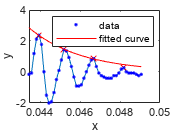


% Amortecimento
result = fit(t_peaks(1:3), peaks(1:3),'exp1');


% Definição dos polos
% polos_im = [-trecho_omega, trecho_omega];
% polos_re = [-k, -k];


% Plotando o trecho com os parâmetros encontrados
figure;
plot(trecho_t, trecho_Vp, t_peaks, peaks, 'xr');
hold on;
plot(result, trecho_t, trecho_Vp);
hold off;

% legend('Sinal amostral', 'Picos', sprintf('%f * exp(-%f * t)', m, k));
% title('Trecho analisado');

% Calculando o G(s) do trecho na força bruta
b_range = linspace(950, 980, 20);
c_range = linspace(21000000, 22000000, 20);
amplitude_range = linspace(12500, 14000, 30);

% Calcula os melhores valores de b, c e amplitude com base no menor erro
[b, c, amp] = testar_impulso_Forca_bruta(b_range, c_range, amplitude_range, trecho_t, trecho_Vp);

Not enough input arguments.

Error in TFINAAAAAL>criarImpulso (line 153)
    y_impulso = amplitude * y_impulso(:);

Error in TFINAAAAAL>testar_impulso_Forca_bruta (line 100)
                    [x_impulso, y_impulso] = criarImpulso(Ns, Ds, trecho_t, amp, false);


% Cria um impulso com base nos valores b, c e amp encontrados
[x_impulso, y_impulso] = impulso(amp, b, c, trecho_t);

% Plota o trecho original comparando o trecho gerado por força bruta
figure;
plot(trecho_t, trecho_Vp, trecho_t, y_impulso, 'r--');
legend('Sinal amostral', 'Sinal gerado por força bruta');
title('Trecho da Sinal Original vs Sinal Gerado por La Place');



% Função Forca_Bruta

function [best_b, best_c, best_amp] = testar_impulso_Forca_bruta(b_range, c_range, amplitude_range, trecho_t, trecho_Vp)
    % Testa valores de b, c e amplitude especificados pelos ranges, retornando a combinação de menor erro
    
    iteracoes = containers.Map;
    for b = b_range
        for c = c_range
            for amp = amplitude_range
                if (b^2 - 4*c) < 0
                    % Define a expressão
                    Ns = [1];
                    Ds = [1, b, c];
                    % Cria o impulso
                    [x_impulso, y_impulso] = criarImpulso(Ns, Ds, trecho_t, amp, false);

                    % todo adicionar erro com o impulso e o valor real
                    iteracoes(sprintf('%f/%f/%f', b, c, amp)) = calculaErroAjuste(trecho_Vp, y_impulso, trecho_t);
                end
            end
        end
    end
    
    % Retorna impulso com menor erro
    [best_b, best_c, best_amp] = get_menor_erro(iteracoes);
end

function [x_impulso, y_impulso] = impulso(amp, b, c, trecho_t)
    % Cria um impulso a partir de valores de amp, b e c
    
    Ns = [amp];
    Ds = [1, b, c];
    [x_impulso, y_impulso] = criarImpulso(Ns, Ds, trecho_t, amp);
end

function [x_impulso, y_impulso] = criarImpulso(Ns, Ds, vetor_tempo, exponencial, exibir, xlim, amplitude)
    % Recebe vetores Ns e Ds, representando os multiplicadores do numerador e denominador da função F(s) de La Place e
    % retornar um vetor do resultado de aplicar um impulso nessa F(s)
    
    % Cria a função G(s)
    Gs = tf(Ns, Ds);
    % Faz Gs sofrer um impulso
    [x_impulso, y_impulso] = impulse(Gs, vetor_tempo);
    
    % Exibe o sinal obtido em uma figura
    if exibir
        fprintf('N(s) = %s\n', mat2str(Ns));
        fprintf('D(s) = %s\n', mat2str(Ds));
        fprintf('Função G(s): %s\n', func2str(Gs));
        
        figure;
        plot(x_impulso, y_impulso);
        title(sprintf('b = %f, c = %f', Ds(2), Ds(3)));
        grid on;
        xlabel('Tempo em segundos');
        ylabel('Amplitude');
        hold on;
        
        if ~isempty(exponencial)
            plot(vetor_tempo, exponencial(1) * exp(-exponencial(2) * vetor_tempo));
        end
        
        xlim(xlim);
    end
    
    % Retorna o impulso
    x_impulso = x_impulso(:);
    y_impulso = amplitude * y_impulso(:);
end

function [b, c, amplitude] = get_menor_erro(iteracoes)
    % Retorna os valores de b, c e amplitude da iteração com menor erro
    
    % Obtém a chave com o menor valor de erro
    [~, chave_min] = min(cell2mat(values(iteracoes)));
    
    % Extrai os valores de b, c e amplitude da chave
    valores = strsplit(chave_min, '/');
    b = str2double(valores{1});
    c = str2double(valores{2});
    amplitude = str2double(valores{3});
end

function erro = calculaErroAjuste(gt, yt, t)
    % Calcula o erro entre um vetor gt e yt, do mesmo tamanho, fazendo a média do quadrado da diferenca entre cada
    % ponto dos vetores
    
    erro = zeros(size(t));
    
    for i = 1:length(t)
        if i <= length(gt) && i <= length(yt)
            erro(i) = (yt(i) - gt(i))^2;
        end
    end
    
    erro = mean(erro);
end

